SUM_st.name='SUM'; 
SUM_st.lat=72.5800018311;
SUM_st.lon=-38.4799995422;
SUM_st.alt=3238;
SUM_st.env='P';
SUM_st.footp='P';


SUM_rdx=read_betsy('sum_2011_2018',SUM_st.name);

SUM_rd2=read_betsy('sum_2005_2016_AE16',SUM_st.name);
SUM_rd=read_betsy('sum_2005_2018_aeth_clap_neph_longformat',SUM_st.name);

datevec(SUM_rd.Time(1))

ans =         2011           5           7           0           0           0


datevec(SUM_rd.Time(end))

ans =         2019           1           1           0           0           0


prctile(SUM_rd.U_S,[5 50 95])

ans =          0         0    5.4875


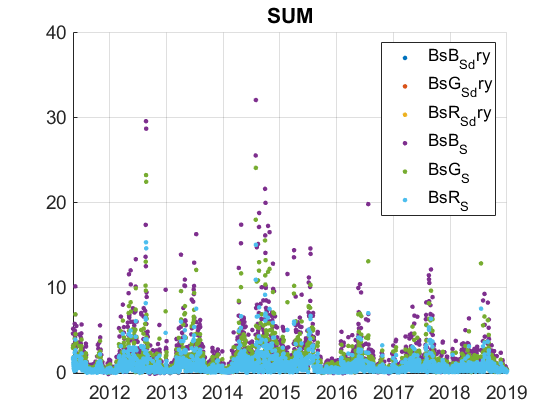

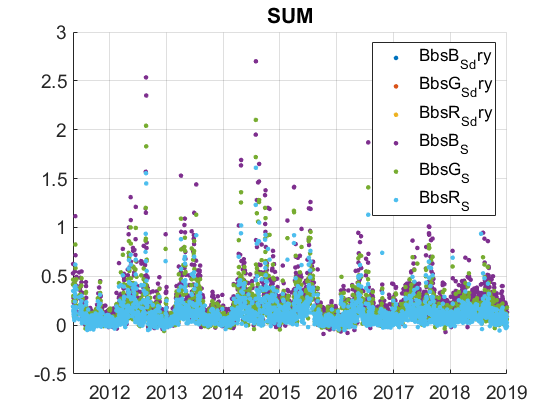

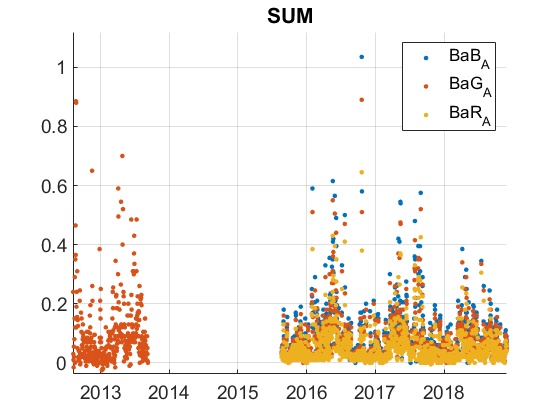

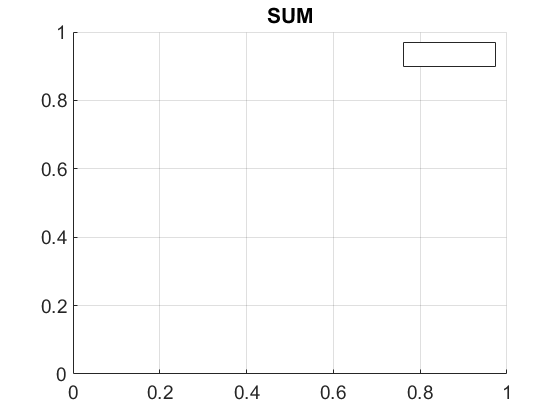

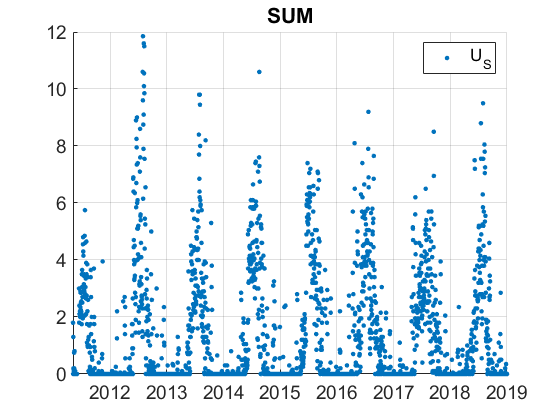

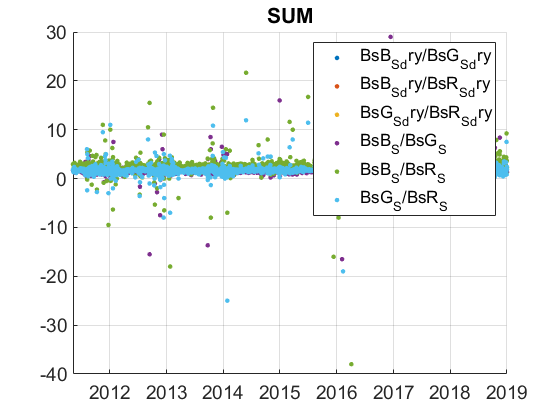

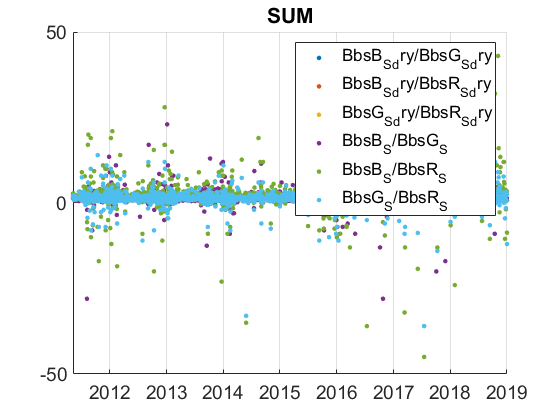

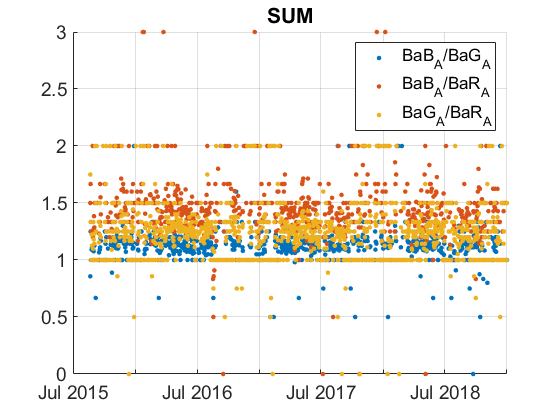

plotFigControl(SUM_rd,SUM_st.name);

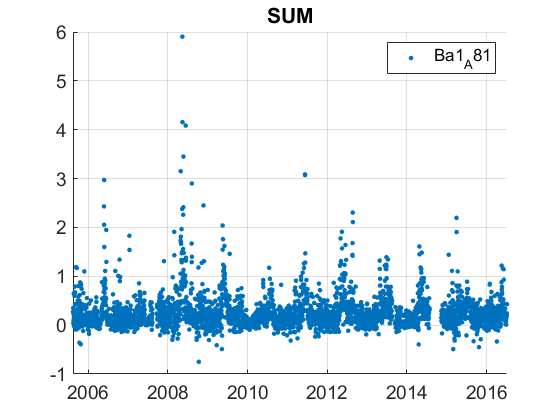

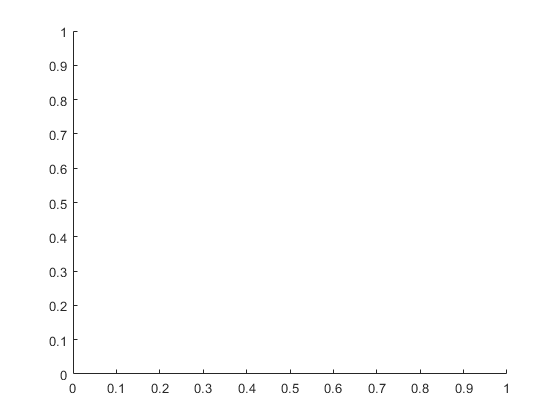

plotFigControl(SUM_rd2,SUM_st.name);

% 1 size cut, ok
% sc: ok, 

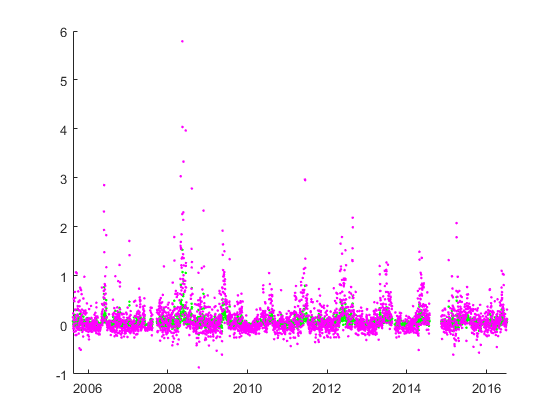

%try to homogeneize AE16 and clap R
px=timerange('2011-07-01','2016-07-07');
ratio=SUM_rd.BaR_A11(px)./SUM_rd2.Ba1_A81(px);
ratio(abs(ratio)==Inf)=NaN;
% % figure
% % plot(SUM_rd.Time(px),ratio,'.');
% % nanmedian(ratio)
% % nanmean(ratio)
% % nanvar(ratio)
diffx=SUM_rd.BaR_A11(px)-SUM_rd2.Ba1_A81(px);
% % figure
% % plot(SUM_rd.Time(px),diffx,'.');
% % nanmedian(diffx)
% % nanmean(diffx)
% % nanvar(diffx)
abs_ratio=SUM_rd2.Ba1_A81.*nanmean(ratio); %=nanmedian of ratio=0.24, nanmean=0.30 better
abs_diff=SUM_rd2.Ba1_A81-0.115;
hold on;
plot(SUM_rd2.Time,abs_ratio,'.g');
plot(SUM_rd2.Time,abs_diff,'.m');


% use the ratio (from red) 
% new dataset by Betsy (longformat): CLAP from 10.5.2011: to use and corrected Ba1
% before
SUM_rd2.BaR_A81=abs_ratio;
SUM_rd=synchronize(SUM_rd,SUM_rd2);
py=timerange('2005-08-13','2011-05-10');
SUM_rd.BaR_A11(py)=SUM_rd2.BaR_A81(py);
SUM_rd.BaR_A=[];


lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
SUM_cal=compute_exp_SSA(SUM_rd,lambdaSC, lambdaAE);
plotFigControl_cal(SUM_cal, SUM_st.name);

%Questions:
%problems:



SUM_tr=SUM_rd; 
SUM_tr.y=year(SUM_tr.Time);
% scat begin at the beginning of a year: 2012
%end: 2018 --> too shot for trend analysis.
%abs begin in 2006, end in 2018
P=timerange('2006-01-01','2019-01-01');
SUM_tr=SUM_tr(P,:);

% %U very low --> no trend in U and dry
names=fieldnames(SUM_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U";"Bs";"Bbs";"Ba1"]) | contains(names,["A81";"SUM"]);
N=names(c);
for i=1:length(N)
    SUM_tr.(N{i})=[];
end
lambdaAE=[467;530;660]*ones(1,4);
SUM_tr.expA_bg=real(-log(SUM_tr.BaB_A11./SUM_tr.BaG_A11)/log(lambdaAE(1)/lambdaAE(2)));

% compute trend only on R with AE16 and CLAP

SUM_tr.BaB_A11=[];
SUM_tr.BaR_A=[];

SUM_result=all_trend_STN(SUM_tr,SUM_st);

SUM_result_D=SUM_result;